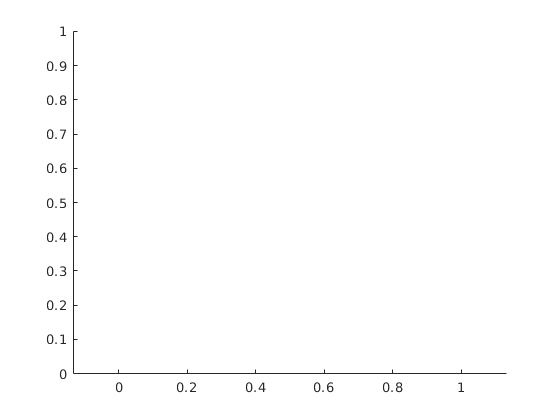

hold on
axis equal

3.6

r = rotation2d(pi/6)

r =     0.8660   -0.5000
    0.5000    0.8660


p1 = [1; 2]

p1 =      1
     2


p2 = [-1; 2]

p2 =     -1
     2


p3 = [-1; -2]

p3 =     -1
    -2


p4 = [1; -2]

p4 =      1
    -2


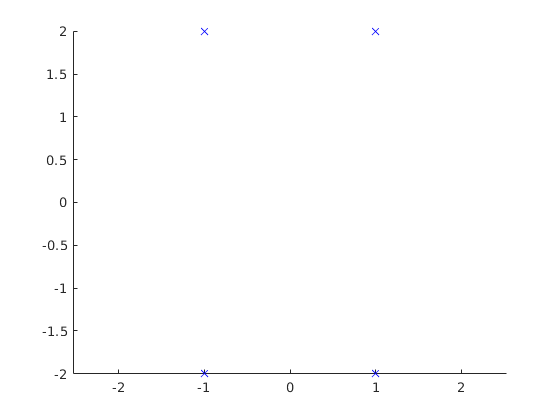


plot(p1(1), p1(2), 'bx', p2(1), p2(2), 'bx', p3(1), p3(2), 'bx', p4(1), p4(2), 'bx')

p1r = r*p1

p1r =    -0.1340
    2.2321


p2r = r*p2

p2r =    -1.8660
    1.2321


p3r = r*p3

p3r =     0.1340
   -2.2321


p4r = r*p4

p4r =     1.8660
   -1.2321


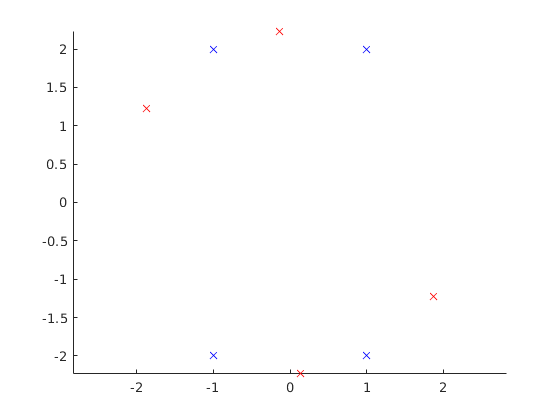


plot(p1r(1), p1r(2), 'rx', p2r(1), p2r(2), 'rx', p3r(1), p3r(2), 'rx', p4r(1), p4r(2), 'rx')

hold off

clf()
hold on
axis equal

rect = [1 -1 -1 1.6 1; 2 2 -2 -2 2]

rect =     1.0000   -1.0000   -1.0000    1.6000    1.0000
    2.0000    2.0000   -2.0000   -2.0000    2.0000


rect_rot = r*rect

rect_rot =    -0.1340   -1.8660    0.1340    2.3856   -0.1340
    2.2321    1.2321   -2.2321   -0.9321    2.2321


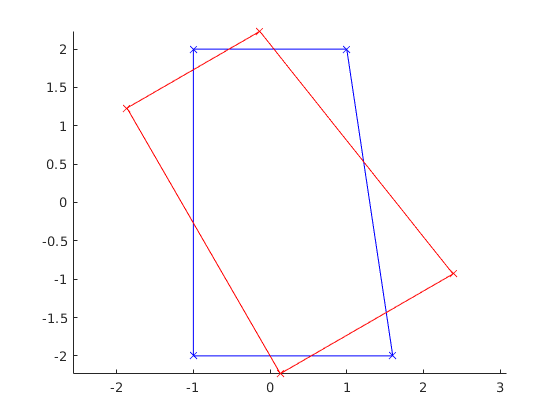


plot(rect(1, :), rect(2, :), 'bx-')
plot(rect_rot(1, :), rect_rot(2, :), 'rx-')

3.8

reflect30 = [
    cosd(2*30) sind(2*30);
    sind(2*30) -cosd(2*30)
]

reflect30 =     0.5000    0.8660
    0.8660   -0.5000



rect_ref = reflect30 * rect

rect_ref =     2.2321    1.2321   -2.2321   -0.9321    2.2321
   -0.1340   -1.8660    0.1340    2.3856   -0.1340


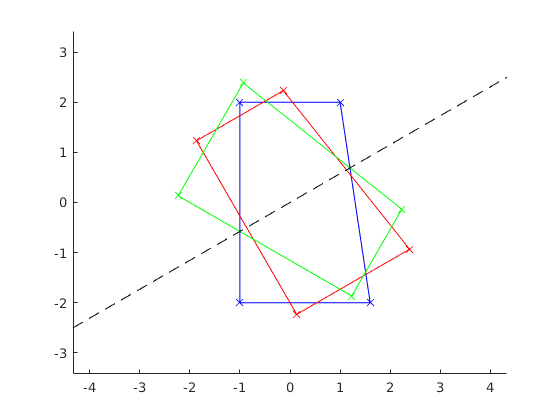

plot(rect_ref(1, :), rect_ref(2, :), 'gx-')
% plot 30 deg angle
plot([-cosd(30)*5 cosd(30)*5], [-sind(30)*5 sind(30)*5], 'k--')

hold off

clf()
hold on
axis equal

3.9


shear = [
    1 k;
    0 1
]

shear =      1     1
     0     1



rect_ref = shear * rect

rect_ref =     3.0000    1.0000   -3.0000   -0.4000    3.0000
    2.0000    2.0000   -2.0000   -2.0000    2.0000


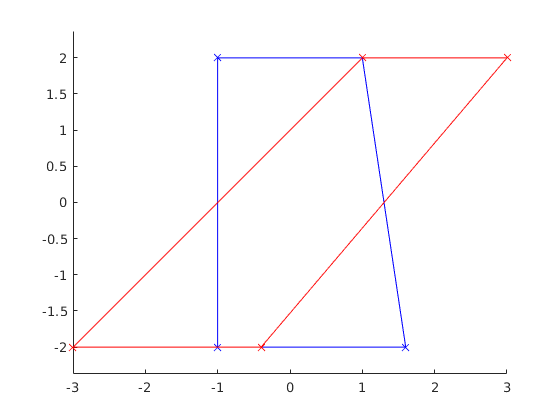

plot(rect(1, :), rect(2, :), 'bx-')
plot(rect_ref(1, :), rect_ref(2, :), 'rx-')